Controllo se è rimasta aperta la porta seriale

if( exist('STM32_ser') )
    delete(STM32_ser);
    clear STM32_ser;
end

Connetto alla seriale

velocita_porta = 9600

velocita_porta = 9600

porte_libere = serialportlist("available")

porte_libere = "COM8"

STM32_ser = serialport(porte_libere(end), velocita_porta, Timeout=1);
configureTerminator(STM32_ser,"CR");

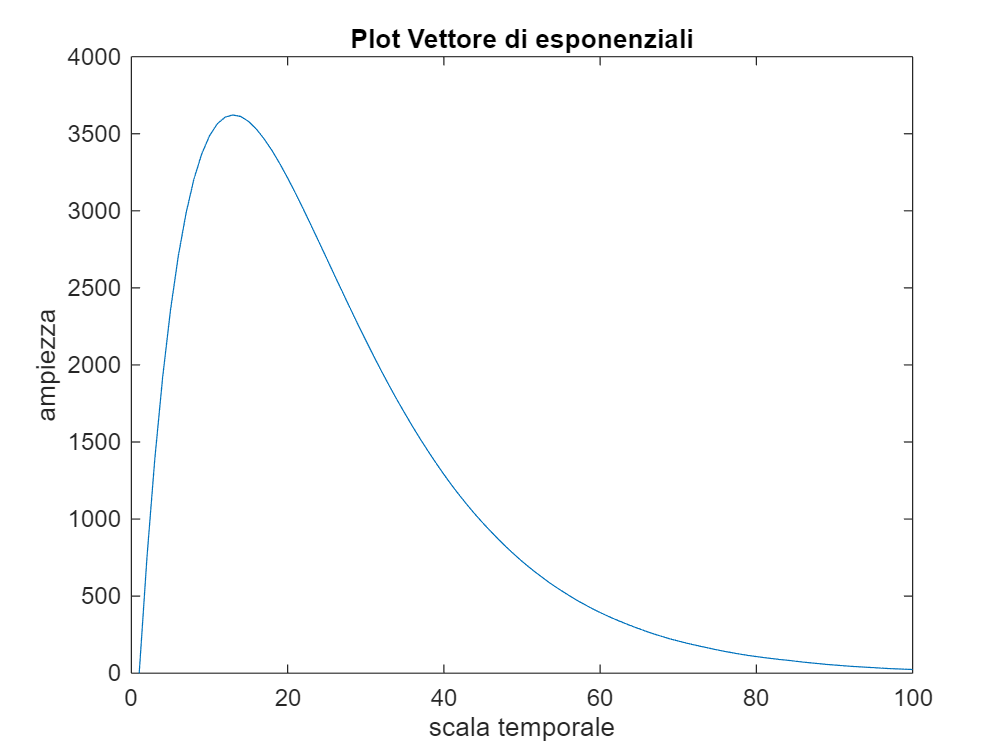

STM32_ser.flush;
STM32_ser.write('e', 'char');

vettore_dati = STM32_ser.read(100,'uint16');

f = figure;

plot(1:length(vettore_dati), vettore_dati)
title("Plot Vettore di esponenziali")
xlabel("scala temporale")
ylabel("ampiezza")